# **Progetto regolatore con luogo delle radici**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento tempo continuo del processo

% parameters
Tau_meca = 0.050;
Tau_sensore = 0.014;
Tau = Tau_sensore + Tau_meca;
T = 0.100;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                       1
  exp(-0.064*s) * -----------
                  0.1 s^2 + s
 
Continuous-time transfer function.



**Definizione della funzione di trasferimento tempo discreto del processo**

%discretizzazione di G
Tc = 0.02;
G_d = c2d(G, Tc)

G_d =
 
           0.001214 z^2 + 0.002345 z + 6.638e-05
  z^(-4) * -------------------------------------
                  z^2 - 1.819 z + 0.8187
 
Sample time: 0.02 seconds
Discrete-time transfer function.



G_d = tf([0.0008186 0.00224 0.0001339], [1 -1.84 0.8404 0 0 0 0 0], Tc) %riscritto in forma canonica

G_d =
 
  0.0008186 z^2 + 0.00224 z + 0.0001339
  -------------------------------------
       z^7 - 1.84 z^6 + 0.8404 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.



pole(G_d)

ans =          0
         0
         0
         0
         0
    0.9975
    0.8425


**Traccio luogo delle radici di G_d**

% poli e zeri di G_d
[poliG_d, zeriG_d] = pzmap(G_d)

poliG_d =          0
         0
         0
         0
         0
    0.9975
    0.8425


zeriG_d =    -2.6752
   -0.0611


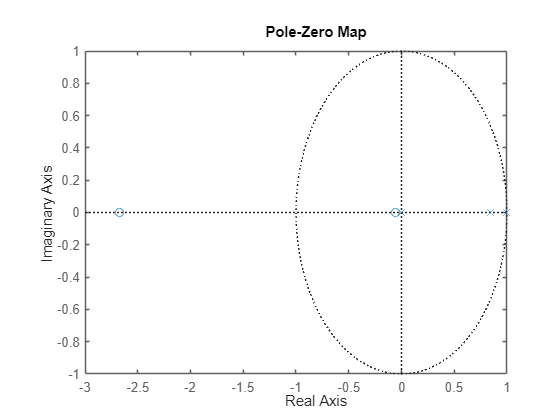

pzmap(G_d)

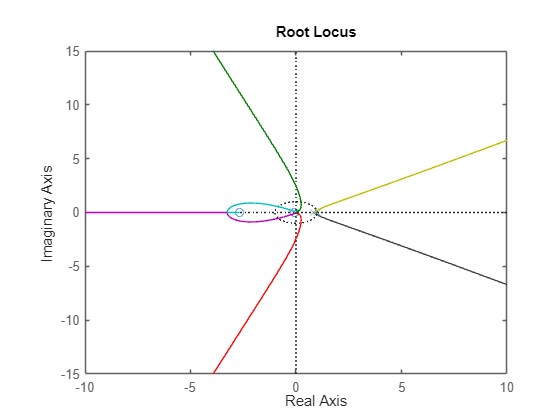


%traccio luogo
rlocus(G_d)

**Opero su luogo delle radici per trovare il regolatore**

% richieste per regolatore:

%  - asintotica stabilità del sistema ad anello chiuso
%  - astatismo a gradino 
%  - tempo assestamento < 0.5s

rltool(G_d, Tc)
% ho trovato la possibile soluzione

% - zero in 0.843
% - 2 poli in -0.477

**Funzioni definitive**

R = C

R =
 
  31.084 (z-0.8425)
  -----------------
          z
 
Name: C
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.



L = R * G_d                 %open loop function

L =
 
  0.025445 (z-0.8425) (z+2.675) (z+0.06114)
  -----------------------------------------
          z^6 (z-0.9975) (z-0.8425)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.



L_close = feedback(L, 1)    %close loop function

L_close =
 
                             0.025445 (z+2.675) (z-0.8425) (z+0.06114)
  -----------------------------------------------------------------------------------------------
  (z-0.8424) (z+0.06114) (z^2 - 1.71z + 0.7499) (z^2 + 0.8597z + 0.2638) (z^2 - 0.2084z + 0.3442)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.



**Qualche test sulla funzione F**

F = L/(1+L)

F =
 
                        0.017226 z^6 (z-0.8425) (z-0.8425) (z-0.9975) (z+2.675) (z+0.06114)
  ---------------------------------------------------------------------------------------------------------------
  z^6 (z-0.9975) (z-0.8488)^2 (z-0.8425) (z-0.7954) (z+0.06114) (z^2 + 0.7973z + 0.2283) (z^2 - 0.2056z + 0.2969)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.



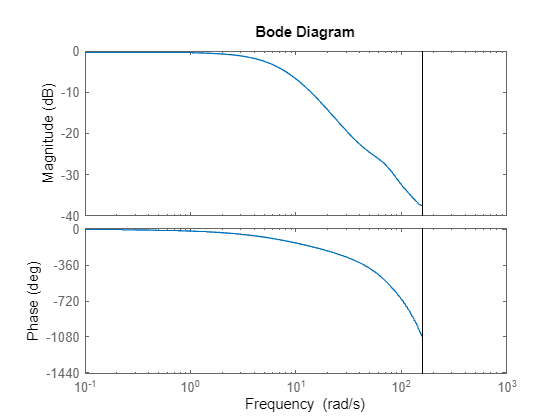


bode(F)

**Qualche test sulla funzione ad anello chiuso**

%TEST

%poles and zeros 
[poli, zeri] = pzmap(L_close)

poli =    0.8457 + 0.1121i
   0.8457 - 0.1121i
   0.8424 + 0.0000i
   0.1038 + 0.5642i
   0.1038 - 0.5642i
  -0.4201 + 0.2755i
  -0.4201 - 0.2755i
  -0.0611 + 0.0000i


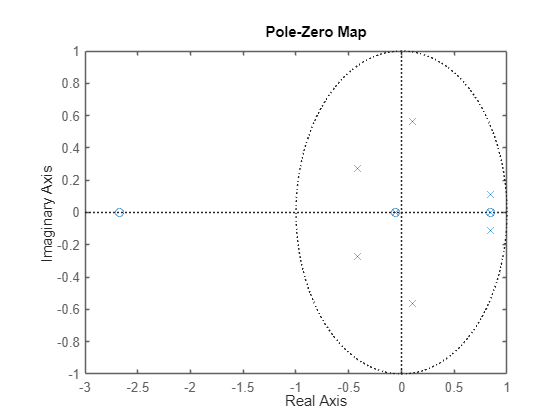

pzmap(L_close)

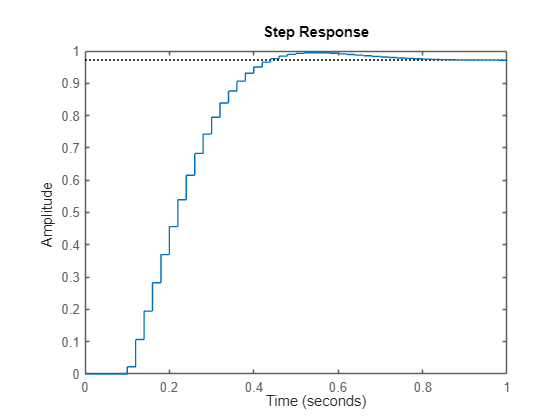



%indicial response
step(L_close)

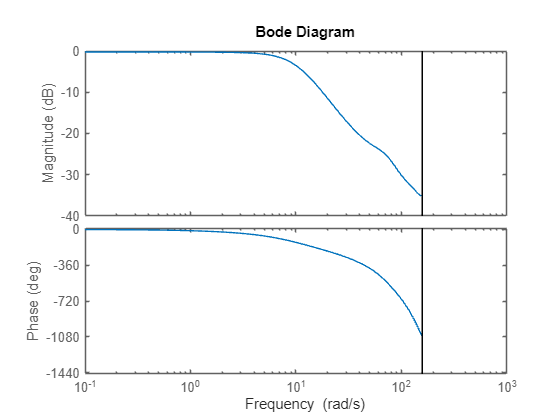



%bode diagram
bode(L_close)